# **MODIFIED** Euler technique:  

# The wheel on a pole and gyroscopic moments 

Let's explore the classic mechanics experiment where we suspend a spinning disc (it's often a bicycle wheel) on a pole (it's often suspended from a rope).  In our case we'll use a solid wheel, and the wheel will be connected to a support tower via a "massless" rod. The support tower allows the wheel assembly to yaw($\phi$), pitch ($\theta$) and the wheel can of course spin ($\Omega$).   

We'll look specificall at modelling this system using the **MODIFIED** Euler equations.

The system that we'll consider is similar (but NOT identical) to the one shown in this [**youtube clip**](https://www.youtube.com/watch?v=NeXIV-wMVUk) made by Prof Lewin.   

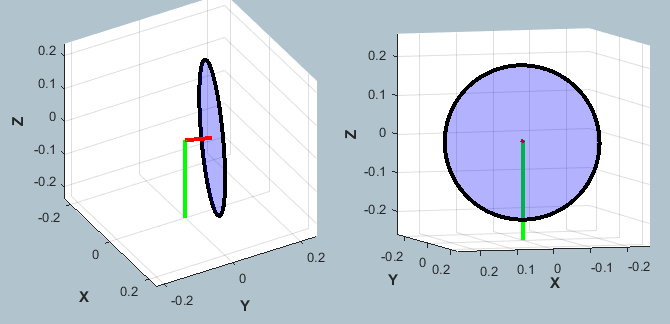 

`Bradley Horton : 20-Sep-2017, bradley.horton@mathworks.com.au`

## **Revision:**

Before looking at this case study, review the tutorial document `bh_CONCEPT_Passive_rots_Body_rates_Euler_rates.mlx.  `Specifically the sections:

- Review the concept of PASSIVE rotation matrices 

- An example of 2 successive PASSIVE rotations

## **Our system:**

OK, the system that we'll consider is shown below:

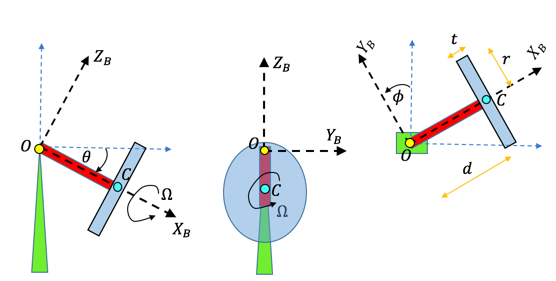

In the diagram above, note the following:

- The B-frame is attached at the Pivot point *O*.

- The B-frame is partially attached to the body - we say "partially", because the B-frame yaws ($\phi$) and pitches ($\theta$) **with** the body ... but ... the body is free to spin relative to the $^BX$axis.

- $\Omega$ is the spin angular velocity of the body relative to the attached B-frame.  The spin velocity occurs along the $^BX$axis.

- We'll use the term "yaw" and "precession" interchangeably.

- Because of the symmetry of the wheel, the inertia matrix relative to the B-frame stays constant even though the wheel spins ($\Omega$) relative to the B-frame.

- As stated in the introduction, the (red) rod that attaches the wheel to the pivot point *O*, is a massless rod.

## Define some model parameters:

- r : (m),  wheel radius

- t : (m),  wheel thickness

- m : (kg), wheel mass

- d : (m),  rod length , really it's the distance from pivot point O to the CoM of the wheel

Load some parameters needed by the Simulink models *- we'll be opening these shortly*

bh_parameters_for_models

And here they are:

whos

  Name         Size            Bytes  Class           Attributes

  EME_BUS      1x1               394  Simulink.Bus              
  d            1x1                 8  double                    
  m            1x1                 8  double                    
  mr           1x1                 8  double                    
  r            1x1                 8  double                    
  rr           1x1                 8  double                    
  t            1x1                 8  double                    
  tr           1x1                 8  double                    



## The inertia matrix for solid cylinder:

Let's calculate the inertia matrix of the wheel.  First we'll determine the inertia about a frame attached to the center of mass *C* of the wheel, then we'll apply the Parallel axis theorem to calculate the inertia about the pivot point *O*. (consult the following reference for inertias of cylinders  [https://en.wikipedia.org/wiki/List_of_moments_of_inertia](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)).

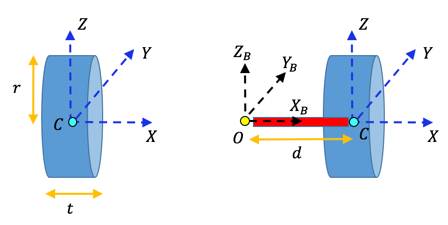

Here's the moment of inertia matrix $^B_CI$ about the cylinder's center of mass:

Ic = [ (m*r^2)/2,   0,                     0;
       0,           m*(3*r^2 + t^2)/12,    0;
       0,           0,                     m*(3*r^2 + t^2)/12;
     ];

% extract the spin axis Inertia term
Ic_xx_val = Ic(1,1) 

Ic_xx_val = 0.0800

And here's the cylinder's moment of inertia matrix $^B_OI$ about the pivot point "O" - note we're simply using the Parallel axis theorem:

dx = d;   dy = 0;   dz = 0;

Io = Ic  +  m*[  (dy^2 + dz^2),        (-dx*dy),        (-dx*dz);
                      (-dy*dx),   (dx^2 + dz^2),        (-dy*dz);
                      (-dz*dx),        (-dz*dy),   (dx^2 + dy^2);  ];                  

Note how the Inertia matrix is still (as expected) a diagonal matrix

% echo the Inertia matrix
Io

Io =     0.0800         0         0
         0    0.0597         0
         0         0    0.0597


## The gravity torque:

**REMEMBER:**  *the {B}-frame will only *yaw($\phi$) and pitch ($\theta$)* with the wheel.  The {B}-frame will NOT roll.  Instead we are defining  *$\Omega$*  as the spin angular velocity of the wheel relative to the attached {B}-frame.  The spin velocity occurs along the *$^BX$*axis.*

The wheel is subjected to a TORQUE due to the wheel's mass and the offset distance "*d*" to the pivot point *O. * In components of the {B}-frame, we can describe the torque applied by gravity as the usual vector ***CROSS PRODUCT*** of the arm length and the applied force, ie:

           $^B_O\tau \enspace = \enspace ^Br \enspace \times \enspace ^B\overrightarrow{mg}
 \enspace = \enspace
\pmatrix{
d \cr 0 \cr 0
}
\times
\pmatrix{
mg.Sin(\theta) \cr 0 \cr -mg.Cos(\theta)
}$ = $\pmatrix{0\cr d.mg.Cos(\theta) \cr 0}$

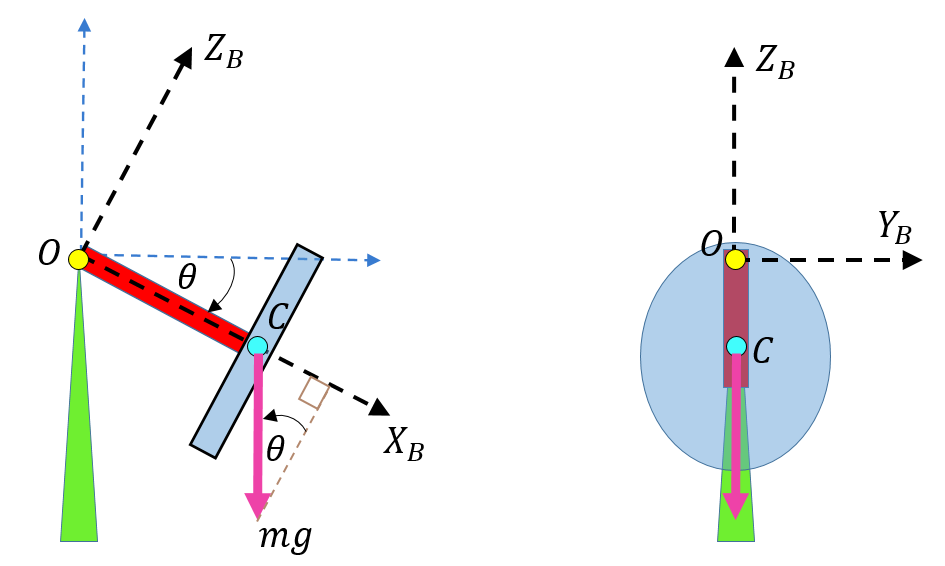

## The Physics of the system:

The equations of motion for this system are defined by the **Modified Euler moment equation** (MEME) for a rigid body -  Note that all terms are expressed in components of the body fixed {B}-frame:

- 
$$^B_OM - (  \enspace
^B_CI. \dot{\Omega} + \omega \times (^B_CI.\Omega)  \enspace)
  \enspace = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


Note that on the left hand side of the Euler moment equation we have the additional "gyroscopic" moments(or torques) caused by the wheel's spin velocity $\Omega$.  

- Remember that $\Omega$ is the spin angular velocity of the body relative to the attached B-frame.  The spin velocity occurs along the $^BX$axis.

Let's consider the ***specific case*** where (this corresponds to our "**Wheel on a pole**" system):

$\Omega = \pmatrix{
\Omega_x \cr
0 \cr 
0
}$,  $\dot{\Omega} = \pmatrix{
\dot{\Omega}_x \cr
0 \cr 
0
}$,  $^B_CI = 
\pmatrix{
^B_CI_{xx} & 0 & 0 \cr
0 & ^B_CI_{yy} & 0 \cr
0 & 0 & ^B_CI_{zz} \cr
}$,  $^B_OI = 
\pmatrix{
^B_OI_{xx} & 0 & 0 \cr
0 & ^B_OI_{yy} & 0 \cr
0 & 0 & ^B_OI_{zz} \cr
}$, $\omega = 
\pmatrix{
\omega_x \cr
\omega_y \cr
\omega_z
}$ where $\omega$ is the angular velocity of the B-frame.

In the following section we're going to substitute the above terms into our **Modified Euler moment equation** (MEME). We'll proceed by first focusing on the LEFT hand side of the MEME, and then we'll focus on the RHS of the EME.

% define some symbolic variables
syms Ic_xx Ic_yy Ic_zz  
syms Io_xx Io_yy Io_zz 
syms omega_x omega_y omega_z 
syms omega_dot_x omega_dot_y omega_dot_z
syms Omega_x  Omega_dot_x

Here's our $^B_OI$:

soI          = [ Io_xx,     0,     0;
                   0,   Io_yy,     0;
                   0,     0,   Io_zz];               

Here's our $^B_CI$:

scI          = [ Ic_xx,     0,     0;
                   0,   Ic_yy,     0;
                   0,     0,   Ic_zz]; 

Here's our $\omega$ and $\dot{\omega}$:    

 sw         =  [omega_x;         omega_y;      omega_z];
 sw_DOT     =  [omega_dot_x;    omega_dot_y;   omega_dot_z]; 

Here's our $\Omega$ and $\dot{\Omega}$:

 sOmega     =  [Omega_x;        0;            0;];
 sOmega_DOT =  [Omega_dot_x;    0;            0;]; 

### OK, let's explore the LEFT hand side of our Modified Euler equation:

- 
$$^B_OM - (  \enspace
^B_CI. \dot{\Omega} + \omega \times (^B_CI.\Omega)  \enspace)
  \enspace = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


First let's look at our **GYROSCOPIC torque** term

-  $^B_CI. \dot{\Omega} + \omega \times (^B_CI.\Omega)$, is:

% PART_A and B
part_A =           scI * sOmega_DOT;
part_B = cross(sw, scI * sOmega);

the_GYRO_TQ = part_A + part_B

$$the\_GYRO\_TQ = \left(\begin{array}{c} {\mathrm{Ic}}_{\mathrm{xx}}\,{\dot{\Omega }}_{x}\\ {\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\omega_{z}\\ -{\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\omega_{y} \end{array}\right)$$

So inserting these gyroscopic moment terms we can write the moment equation as: 

- 
$$^B_OM - \pmatrix{
^B_CI_{xx}\enspace . \enspace \dot{\Omega}_x \cr
\omega_z \enspace . \enspace ^B_CI_{xx}\enspace . \enspace \Omega_x \cr
-1 \times \omega_y \enspace . \enspace ^B_CI_{xx}\enspace . \enspace \Omega_x

}$$

$$  \enspace = \enspace 
^B_OI.\dot{\omega} 
\enspace
+
\enspace
 \omega \times (^B_OI.\omega) $$


### OK, let's explore the RIGHT hand side of our Modified Euler equation:

- 
$$^B_OM - (  \enspace
^B_CI. \dot{\Omega} + \omega \times (^B_CI.\Omega)  \enspace)
  \enspace = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


If we now focus on the RHS of our equation of motion, ie:

-    $^B_OI.\dot{\omega} 
\enspace
+
\enspace
 \omega \times (^B_OI.\omega) $ ,  we get

tmp_RHS = soI*sw_DOT + cross(sw, soI*sw)

$$tmp\_RHS = \left(\begin{array}{c} {\mathrm{Io}}_{\mathrm{xx}}\,{\dot{\omega }}_{x}-{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{y}\,\omega_{z}+{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{y}\,\omega_{z}\\ {\mathrm{Io}}_{\mathrm{yy}}\,{\dot{\omega }}_{y}+{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{z}-{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{x}\,\omega_{z}\\ {\mathrm{Io}}_{\mathrm{zz}}\,{\dot{\omega }}_{z}-{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{y}+{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{x}\,\omega_{y} \end{array}\right)$$

So our system moment equation can now be written as:

- $\pmatrix{
^B_OM_x  \cr
^B_OM_y  \cr
^B_OM_z  \cr
}  - 

$$ \pmatrix{
^B_CI_{xx}\enspace . \enspace \dot{\Omega}_x \cr
\omega_z \enspace . \enspace ^B_CI_{xx}\enspace . \enspace \Omega_x \cr
-1 \times \omega_y \enspace . \enspace ^B_CI_{xx}\enspace . \enspace \Omega_x

}$ =  $ \pmatrix{
^B_OI_{xx} \thinspace . \thinspace \dot{\omega_x} + \omega_y\omega_z \thinspace. \thinspace (^B_OI_{zz}-^B_OI_{yy}) 
\cr
^B_OI_{yy} \thinspace . \thinspace \dot{\omega_y} + \omega_x\omega_z \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{zz})
\cr
^B_OI_{zz} \thinspace . \thinspace \dot{\omega_z} + \omega_x\omega_y \thinspace. \thinspace (^B_OI_{yy}-^B_OI_{xx})
}$

### So or Modified Euler equation finally becomes:

- 
$$^B_OM - (  \enspace
^B_CI. \dot{\Omega} + \omega \times (^B_CI.\Omega)  \enspace)
  \enspace = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


syms Mb_x  Mb_y  Mb_z

Mb = [Mb_x;  Mb_y;  Mb_z];

EQ = (Mb - the_GYRO_TQ) == (tmp_RHS)

$$EQ = \left(\begin{array}{c} {\mathrm{Mb}}_{x}-{\mathrm{Ic}}_{\mathrm{xx}}\,{\dot{\Omega }}_{x}={\mathrm{Io}}_{\mathrm{xx}}\,{\dot{\omega }}_{x}-{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{y}\,\omega_{z}+{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{y}\,\omega_{z}\\ {\mathrm{Mb}}_{y}-{\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\omega_{z}={\mathrm{Io}}_{\mathrm{yy}}\,{\dot{\omega }}_{y}+{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{z}-{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{x}\,\omega_{z}\\ {\mathrm{Mb}}_{z}+{\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\omega_{y}={\mathrm{Io}}_{\mathrm{zz}}\,{\dot{\omega }}_{z}-{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{y}+{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{x}\,\omega_{y} \end{array}\right)$$

And recall the original symbol list

## Substitute Euler Angles into these ODEs:

See `bh_CONCEPT_Passive_rots_Body_rates_Euler_rates.mlx`` f`or a derivation on the relationship between Euler rates and body frame andular velocity, specifically the section:

- An example of 2 successive PASSIVE rotations

Recall that our attached B-frame will yaw($\phi$) and pitch ($\theta$) with the wheel ..... BUT the wheel spins relative to the B-frame with an angular velocity of spin ($\Omega$).  Because only 2 Euler angles describe our B-frame motion, we have:

- $\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{c}
-\phi^˙ \ldotp \mathrm{sin}\left(\theta \right)\\
\theta^˙ \\
\phi^˙ \ldotp \mathrm{cos}\left(\theta \right)
\end{array}\right\rbrack$        and          $\left\lbrack \begin{array}{c}
{\omega^˙ }_x \\
{\omega^˙ }_y \\
{\omega^˙ }_z 
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{c}
-\phi^¨ \ldotp \mathrm{sin}\left(\theta \right)\;\;\;\;\;+\;\;-\phi^˙ \ldotp \theta^˙ \ldotp \mathrm{cos}\left(\theta \right)\;\;\\
\theta^¨ \\
\phi^¨ \ldotp \mathrm{cos}\left(\theta \right)\;-\phi^˙ \ldotp \theta^˙ \ldotp \mathrm{sin}\left(\theta \right)\;
\end{array}\right\rbrack$

So let's substitute these relationships into our Modified Euler equation:

syms  phi          theta        
syms  phi_dot      theta_dot     
syms  phi_ddot     theta_ddot   

my_wx     = -1*phi_dot*sin(theta);
my_wy     = theta_dot;
my_wz     = phi_dot*cos(theta);

my_wx_dot = -1*phi_ddot*sin(theta) +  -1*phi_dot*theta_dot*cos(theta);
my_wy_dot = theta_ddot;
my_wz_dot = phi_ddot*cos(theta)  + -1*phi_dot*theta_dot*sin(theta);

EQ = subs(EQ, [omega_dot_x omega_dot_y omega_dot_z], [my_wx_dot, my_wy_dot, my_wz_dot]);

EQ = subs(EQ, [omega_x omega_y omega_z], [my_wx, my_wy, my_wz])

$$EQ = \left(\begin{array}{c} {\mathrm{Mb}}_{x}-{\mathrm{Ic}}_{\mathrm{xx}}\,{\dot{\Omega }}_{x}={\mathrm{Io}}_{\mathrm{zz}}\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)-{\mathrm{Io}}_{\mathrm{yy}}\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)-{\mathrm{Io}}_{\mathrm{xx}}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)+\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)\\ {\mathrm{Mb}}_{y}-{\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\dot{\varphi }\,\cos\left(\theta \right)={\mathrm{Io}}_{\mathrm{yy}}\,\ddot{\theta }-{\mathrm{Io}}_{\mathrm{xx}}\,{\dot{\varphi }}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+{\mathrm{Io}}_{\mathrm{zz}}\,{\dot{\varphi }}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\\ {\mathrm{Mb}}_{z}+{\mathrm{Ic}}_{\mathrm{xx}}\,\Omega_{x}\,\dot{\theta }={\mathrm{Io}}_{\mathrm{zz}}\,\left(\ddot{\varphi }\,\cos\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right)\right)+{\mathrm{Io}}_{\mathrm{xx}}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right)-{\mathrm{Io}}_{\mathrm{yy}}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

Next, let's solve for:

- $\phi^¨$   and   $\theta^¨$   and   $\Omega^˙$

my_sol = solve(EQ, [phi_ddot theta_ddot, Omega_dot_x])

my_sol = struct with fields:
       phi_ddot: [1×1 sym]
     theta_ddot: [1×1 sym]
    Omega_dot_x: [1×1 sym]


## Convert the ODEs into a MATLAB function block:

Should I make a MATLAB function block

bh_tf_make_MLFblock = false;

OK then do it:

if(true == bh_tf_make_MLFblock)
    my_block = 'bh_tmp_model/tmp_block';
    new_system('bh_tmp_model');
    open_system('bh_tmp_model')
    matlabFunctionBlock(my_block, ...
                       my_sol.phi_ddot, my_sol.theta_ddot, my_sol.Omega_dot_x, ...
                       'Outputs', {'phi_DOT_DOT','theta_DOT_DOT', 'BIG_Omega_DOT'} ...
               )
end

## The Simulink model:

Our system equation of motion is a beautiful thing ..... but how do we make this mathematics come alive?  How do we get confidence that what we see in the real world (... and on youtube) is explained by our maths ? Well, the easiest way to solve our moment equations is to model/represent these equations in Simulink.  Open and explore the following Simulink model `<bh_wheel_dynamics_COMPARE_hand_SEME_to_MEME>` .  

  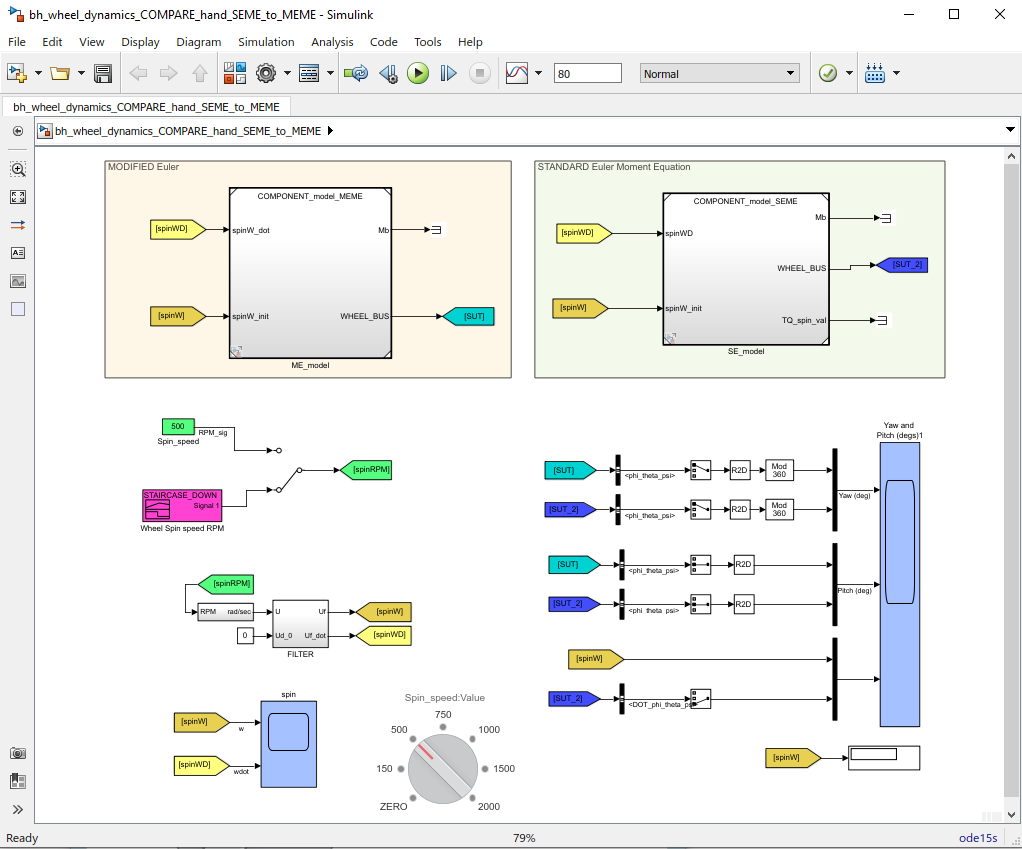      

Open and run the Simulink model:

% open_system('bh_wheel_dynamics_COMPARE_hand_SEME_to_MEME')                   

# **APPENDIX_A:**  Here's another way to model this system.

Review the model called <`bh_wheel_dynamics_COMPARE_hand_SEME_to_simscape`>.  Here we've modelled the same "wheel on a pole" system ... but we've used Simscape to do it.  Simscape uses model building elements such as "joints, bodies, sensors":   And it has a great visualization tool called *Mechanics Explorer* to help you view your assembled machine.